# KF tuning with fminsearch optimization

The search variables $x_1 ,x_2$ are the exponents of $q_i =e^{x_1 }$ and $q_F =e^{x_2 }$ to ensure positiveness

clc
clf
clear all
close all
rng(0)

## Load data

data = load('KF_TuningData.mat').out';

## Initialize

qi_init = 1e-5;
qF_init = 1e-5;
x_init = log([qi_init, qF_init]);

## Cost function wrapper

do_plot = false;
obj_fcn = @(u) KF_simulate(struct('qi', exp(u(1)), 'qF', exp(u(2))), data, do_plot);

## Optimize

options = optimset('Display', 'iter', ...
                   'TolFun', 1e-10, ...
                   'TolX', 1e-10, ...
                   'MaxIter', 1000);

tic
[x_opt, cost_min] = fminsearch(obj_fcn, x_init, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1       4.4884e-05         
     1            3       4.4884e-05         initial simplex
     2            5       3.6191e-05         expand
     3            7      2.86537e-05         expand
     4            9        8.473e-06         expand
     5           11        8.473e-06         contract inside
     6           13        8.473e-06         contract inside
     7           15        8.473e-06         contract inside
     8           17        8.473e-06         contract inside
     9           19        8.473e-06         contract inside
    10           21        8.473e-06         contract inside
    11           23        8.473e-06         contract inside
    12           25        8.473e-06         contract inside
    13           27        8.473e-06         contract inside
    14           29        8.473e-06         contract inside
    15           31        8.473e-06         contract outside
    16  

toc

Elapsed time is 104.080442 seconds.



qi_opt = exp(x_opt(1));
qF_opt = exp(x_opt(2));
fprintf('%.10f', qi_opt)

0.0010000000

fprintf('%.10f', qF_opt)

0.0006155507

## Plot resulting filtering

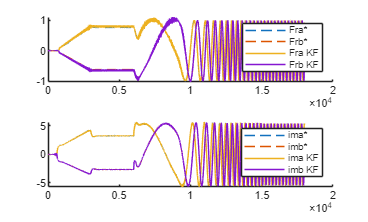

ans = 3.0004e-06

x = struct();
x.qi = qi_opt;
x.qF = qF_opt;
do_plot = true;
KF_simulate(x, data, do_plot)